n = 12800; x = linspace(-1,1,n); y = x(randperm(n)) + rand(1,n) - 0.5;

c = ones(n,1)/n;
r = pdf('Normal',y,0,1)'; r = r/sum(r);
X0 = r*c';
C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = norm(y(i)-x(j))^2;
    end
end

## Inverse function method to solve OT

[~,I] = sort(y);
X_opt = zeros(n,n);
j=1;
i=1;
resid_j = 1/n;
r0 = r(I);
while (i<=n&&j<=n)
    if resid_j>=r0(i)
        X_opt(i,j)=X_opt(i,j)+r0(i);
        resid_j=resid_j-r0(i);
        r0(i)=0;
        i=i+1;
    else
        X_opt(i,j)=X_opt(i,j)+resid_j;
        j=j+1;
        r0(i)=r0(i)-resid_j;
        resid_j=1/n;
    end
end
X_opt(I,:) = X_opt;
f_opt = trace(C'*X_opt);
feas = norm(X_opt*ones(n,1) - r) + norm(X_opt'*ones(n,1) - c);
str = ['optimal value =',num2str(f_opt),', feasibility residual =',num2str(feas)];
disp(str);

optimal value =0.0072515, feasibility residual =1.1276e-16


## Accelerated RBCD

maxiter = 10000;
M = ceil(sqrt(10*n));
X1 = X0;
[fval_arbcd,time_arbcd,feas_arbcd,X2,card_arbcd]=ARBCD(r,c,n,X1,f_opt,C,M,maxiter,1);

iter = 1000, accuracy = 4.0517e-06
number of successful iterations =1000
iter = 1000, accuracy = 3.3969e-06
number of successful iterations =1000
iter = 1000, accuracy = 5.145e-07
number of successful iterations =1000
iter = 1000, accuracy = 1.648e-16
number of successful iterations =1000
iter = 1000, accuracy = 1.8451e-06
number of successful iterations =1000


## Plot

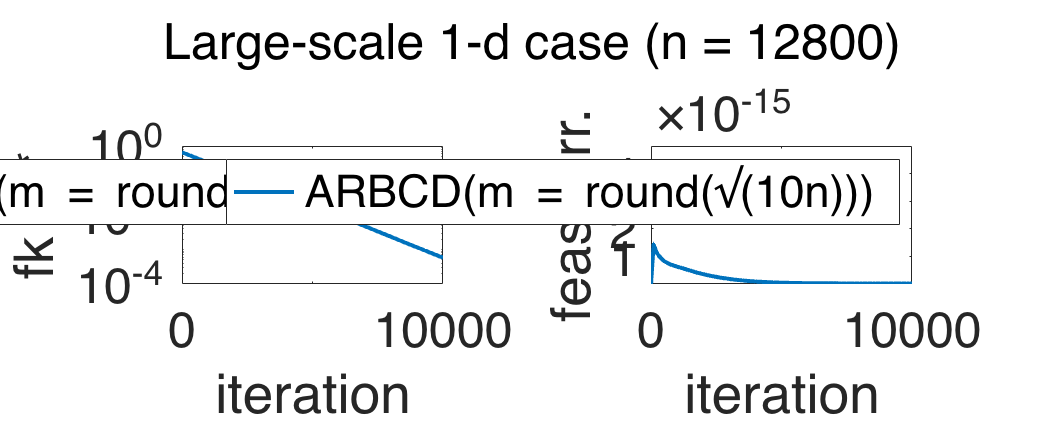

figure('Position', [10 10 1500 600])
subplot(1,2,1)
semilogy(0:100:10000,fval_arbcd,'LineWidth',2)
legend('ARBCD(m = round(\surd(10n)))','location','northeast')
xlabel('iteration')
ylabel('fk - f*')
set(gca,'FontSize',25)
subplot(1,2,2)
plot(0:100:10000,feas_arbcd,'LineWidth',2)
xlabel('iteration')
ylabel('feas. err.')
ylim([1e-17 5e-15])
yticks([0,1,2,3,4,5]*1e-15)
legend('ARBCD(m = round(\surd(10n)))','location','northeast')
sgtitle(['Large-scale 1-d case (n = ', num2str(n),')'],'FontSize',25)
set(gca,'FontSize',25)